% complete quintic example
%% Exam june 2021

A = [1, 1, 1]'

A =      1
     1
     1


B = [-1, 5, 0]'

B =     -1
     5
     0


s_0 = 0;
s_1 = 1;

s_0_dot = 0;
s_1_dot = 0;

s_0_dd = 0;
s_1_dd = 0;

[a, b, c, d, e, f] = quintic_poly_compute_coeff(s_0, s_1, s_0_dot, s_1_dot, s_0_dd, s_1_dd, T, false)

a = 6

b = -15

c = 10

d = 0

e = 0

f = 0

syms t real;
T = 2.5;
s = quintic_poly(a, b, c, d, e, f, t/T)

$$s = \frac{192\,t^{5}}{3125}-\frac{48\,t^{4}}{125}+\frac{16\,t^{3}}{25}$$

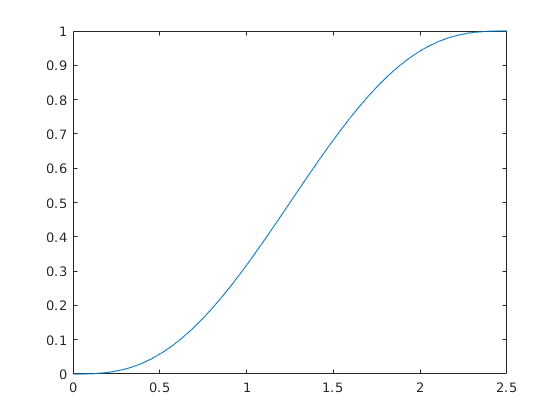

plot_function(s, t, [0, T])

s_dot = diff(s, t)

$$s\_dot = \frac{192\,t^{4}}{625}-\frac{192\,t^{3}}{125}+\frac{48\,t^{2}}{25}$$

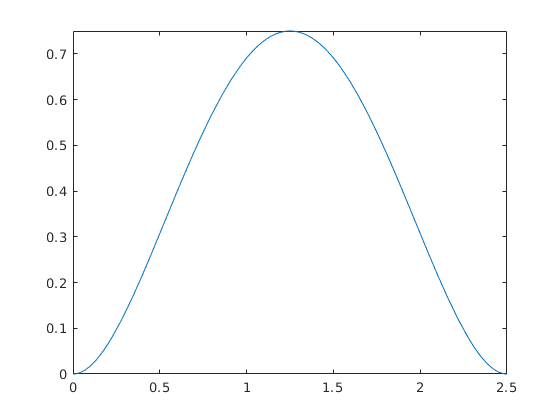

plot_function(s_dot, t, [0, T])

[x, y] = find_abs_maximum_function(s_dot, t)

x = 1.2500

y = 0.7500

max_s_dot = x;

s_dd = diff(s_dot, t)

$$s\_dd = \frac{768\,t^{3}}{625}-\frac{576\,t^{2}}{125}+\frac{96\,t}{25}$$

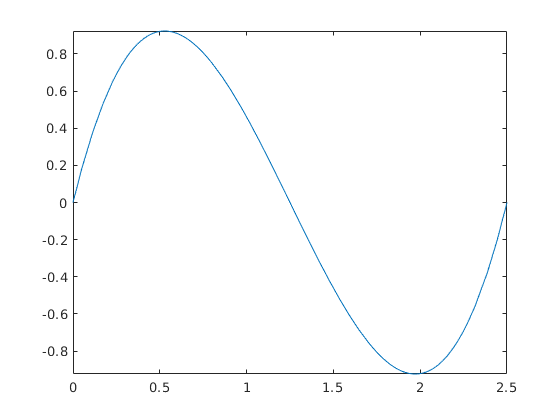

plot_function(s_dd, t, [0, T])

[x, y] = find_abs_maximum_function(s_dd, t)

x = 0.5283

y = 0.9238

max_s_dd = x;

% complete trajectory
p = A + s*(B-A)

$$p = \left(\begin{array}{c} -\frac{384\,t^{5}}{3125}+\frac{96\,t^{4}}{125}-\frac{32\,t^{3}}{25}+1\\ \frac{768\,t^{5}}{3125}-\frac{192\,t^{4}}{125}+\frac{64\,t^{3}}{25}+1\\ -\frac{192\,t^{5}}{3125}+\frac{48\,t^{4}}{125}-\frac{16\,t^{3}}{25}+1 \end{array}\right)$$

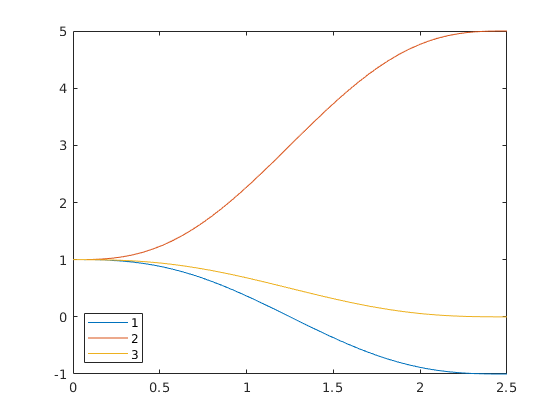

plot_function(p, t, [0, T])

p_dot = diff(p, t)

$$p\_dot = \left(\begin{array}{c} -\frac{384\,t^{4}}{625}+\frac{384\,t^{3}}{125}-\frac{96\,t^{2}}{25}\\ \frac{768\,t^{4}}{625}-\frac{768\,t^{3}}{125}+\frac{192\,t^{2}}{25}\\ -\frac{192\,t^{4}}{625}+\frac{192\,t^{3}}{125}-\frac{48\,t^{2}}{25} \end{array}\right)$$

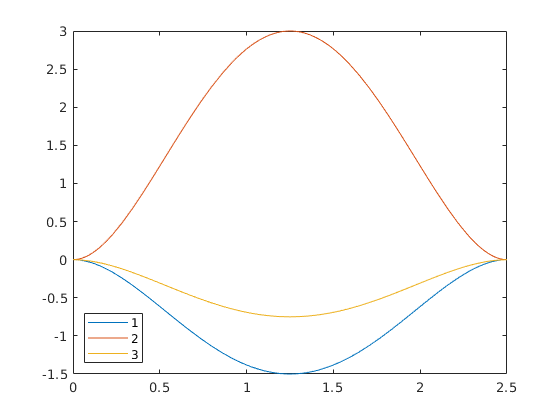

plot_function(p_dot, t, [0, T])

max_p_dot = subs(p_dot, {t}, {max_s_dot})

$$max\_p\_dot = \left(\begin{array}{c} -\frac{3}{2}\\ 3\\ -\frac{3}{4} \end{array}\right)$$

max_p_dot = eval(norm(max_p_dot))              

max_p_dot = 3.4369

p_dd = diff(p_dot, t)

$$p\_dd = \left(\begin{array}{c} -\frac{1536\,t^{3}}{625}+\frac{1152\,t^{2}}{125}-\frac{192\,t}{25}\\ \frac{3072\,t^{3}}{625}-\frac{2304\,t^{2}}{125}+\frac{384\,t}{25}\\ -\frac{768\,t^{3}}{625}+\frac{576\,t^{2}}{125}-\frac{96\,t}{25} \end{array}\right)$$

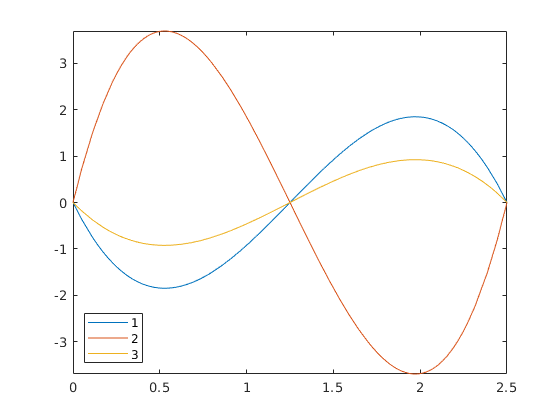

plot_function(p_dd, t, [0, T])

max_p_dd = eval(subs(p_dd, {t}, {max_s_dd}))

max_p_dd =    -1.8475
    3.6950
   -0.9238


max_p_dd = norm(max_p_dd)

max_p_dd = 4.2332

% orientation

R_a = [0 1 0;
    1 0 0;
    0 0 -1]

R_a =      0     1     0
     1     0     0
     0     0    -1


R_b = [-1/sqrt(2) 0 1/sqrt(2);
    0 -1 0;
    1/sqrt(2) 0 1/sqrt(2)]

R_b =    -0.7071         0    0.7071
         0   -1.0000         0
    0.7071         0    0.7071


R = R_a'*R_b

R =          0   -1.0000         0
   -0.7071         0    0.7071
   -0.7071         0   -0.7071


[theta, r] = get_theta_r(R, 'pos')

theta = 2.5936

r =    -0.6786
    0.6786
    0.2811


theta_t = s*theta

$$theta\_t = \frac{17520562457564391\,t^{5}}{109951162777600000}-\frac{17520562457564391\,t^{4}}{17592186044416000}+\frac{5840187485854797\,t^{3}}{3518437208883200}$$

R_t = R_a*angle_axis_rotation_direct(r, theta_t);

R_0 = eval(subs(R_t, {t}, {0}))

R_0 =      0     1     0
     1     0     0
     0     0    -1


R_T_2 = eval(subs(R_t, {t}, {T/2}))

R_T_2 =    -0.0653    0.6065    0.7924
    0.6065   -0.6065    0.5142
    0.7924    0.5142   -0.3282


R_T = eval(subs(R_t, {t}, {T}))

R_T =    -0.7071   -0.0000    0.7071
   -0.0000   -1.0000   -0.0000
    0.7071   -0.0000    0.7071


theta_dot = diff(theta_t, t)

$$theta\_dot = \frac{17520562457564391\,t^{4}}{21990232555520000}-\frac{17520562457564391\,t^{3}}{4398046511104000}+\frac{17520562457564391\,t^{2}}{3518437208883200}$$

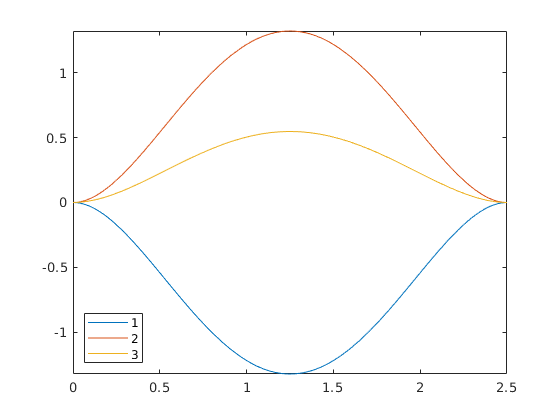

omega= r*theta_dot;
plot_function(omega, t, [0, T])

[x, y] = find_abs_maximum_function(norm(omega), t)

x = 1.2500

y = 1.9452

omega_max = eval(subs(omega, {t}, {x}))

omega_max =    -1.3200
    1.3200
    0.5468


theta_dd = diff(theta_dot, t)

$$theta\_dd = \frac{17520562457564391\,t^{3}}{5497558138880000}-\frac{52561687372693173\,t^{2}}{4398046511104000}+\frac{17520562457564391\,t}{1759218604441600}$$

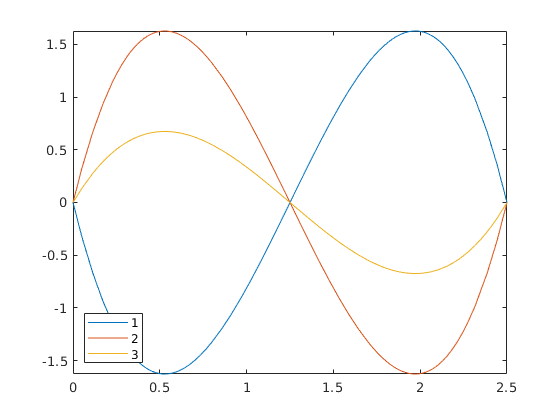

omega_dot = r*theta_dd;
plot_function(omega_dot, t, [0, T])

[x, y] = find_abs_maximum_function(norm(omega_dot), t)

x = 0.5283

y = 2.3958

omega_dot_max = eval(subs(omega_dot, {t}, {x}))

omega_dot_max =    -1.6258
    1.6258
    0.6734
